# What should the basis functions be for fitting the raw lip signals?

We model the lip fluorescence in the 500-600nm band.  We find good fits to much of the data, after accounting for the presence of blood in the stromal layer.

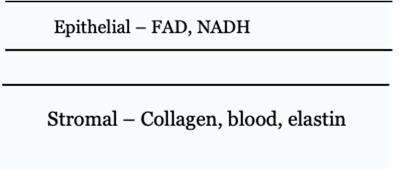

We experimented with various fluorophores.  Based on the anatomy, we apply blood transmittance to collagen and elastin, but not FAD. There are notes about what we tried below, but the main conclusion is that collagen through blood plus FAD does a good job for the lip. When we included elastin, it was never used by the fitting algorithm.  

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

Something to remember when we write.  When you measure samples, or with an endoscope, you may be able to see different fluorophores.  The global (raw) signal, however, may be dominated by one of the fluorophores with only relatively small contributions from the others.  In this case, it appears that collagen through oxygen is the dominant signal in 500-600 band.

We still have things we will try with Keratin, maybe some deoxy.  But we are pretty darn close and it is enough for an image systems definition to find the standard values.  The regularity in the data alone across the subjects and levels is enough.  These comments apply to both the Lip and Tongue data at all excitation wavelengths.

3/4 of the blood is oxygenated.  When we go deeper, we might see the effects of deoxy.  To examine that idea, we might apply the deoxy transmittance to collagen as well, we added that in as an additional column vector in the fluorophore basis.  We let the lsnoneg fit choose how much it wanted of the two types of collagen transmittances.  For the lip data, the deoxy didn't really change anything.

**Caution: ** We have multiple data sets describing the emissions of each of these fluorophores in the isetfluorescence repository.  The literature does not always agree on the emission matrix. 

## Programming notes

**Repositories**: isetcam, isetfluorescence and oe_tongue_lip

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Initialize parameters

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Select the fluorophores 

We create the base fluorophore emissions matrix.  It does not include blood (fluorophoresB).  Below, we sweep through different potential levels of blood optical density, checking how well the modified fluorophore matrix predicts the data samples.  Notice that the effective optical density of blood can depend on the wavelength of the excitation light.  Some lights will penetrate into the skin (substrate) more deeply than others, thus creating a longer path through the blood.

We tried many fluorophore files from the literature. These are described in in **s_oeFluorophoreEmissions.mlx**.  

Apart from FAD, all of the fluorophore emission spectra decline in the wave band from 500-600nm.  They exact emissions differ between labs, but the slopes are similar.

For the lip, there is no keratin, porphyrins, or chlorophyll.  We selected which to use in the s_oeBloodFluorophoreBasis.mlx script.

Here are notes about things we tried.

- fluorophoreNames = {'CollagenWuQu','NADH_webfluor','FADLin'};

- fluorophoreNames = {'CollagenWuQu','FADLin'}; 

- fluorophoreNames = {'CollagenWuQu','FADValdez'};

- fluorophoreNames = {'CollagenWuQu','FAD_webfluor'};

- fluorophoreNames = {'CollagenWuQu','elastin_webfluor','FADValdez'};

- fluorophoreNames = {'collagen7','elastin_webfluor','FADValdez'};

- fluorophoreNames = {'collagen1','elastin_webfluor','FAD_webfluor','NADH_webfluor'};

- fluorophoreNames = {'collagen1'};   % Interesting, but not great

- fluorophoreNames = {'elastin_webfluor','FADValdez'}; 

- fluorophoreNames = {'elastin_webfluor'};  

We should also try deoxygenated blood at some point.

## Create fluorophore matrix and read database

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

The logic is to read all the data for each subject at both 405 nm and 415 nm, and at all intensity levels. The data from different days are sometimes from different locations.

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

rmse = zeros(size(subjects));
odError = zeros(numel(odLevels),numel(subjects));
ods = zeros(numel(subjects),1);    

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 8.00
OD across subjects for 405/415nm 7.00
OD across subjects for 405/415nm 5.00
OD across subjects for 405/415nm 5.00


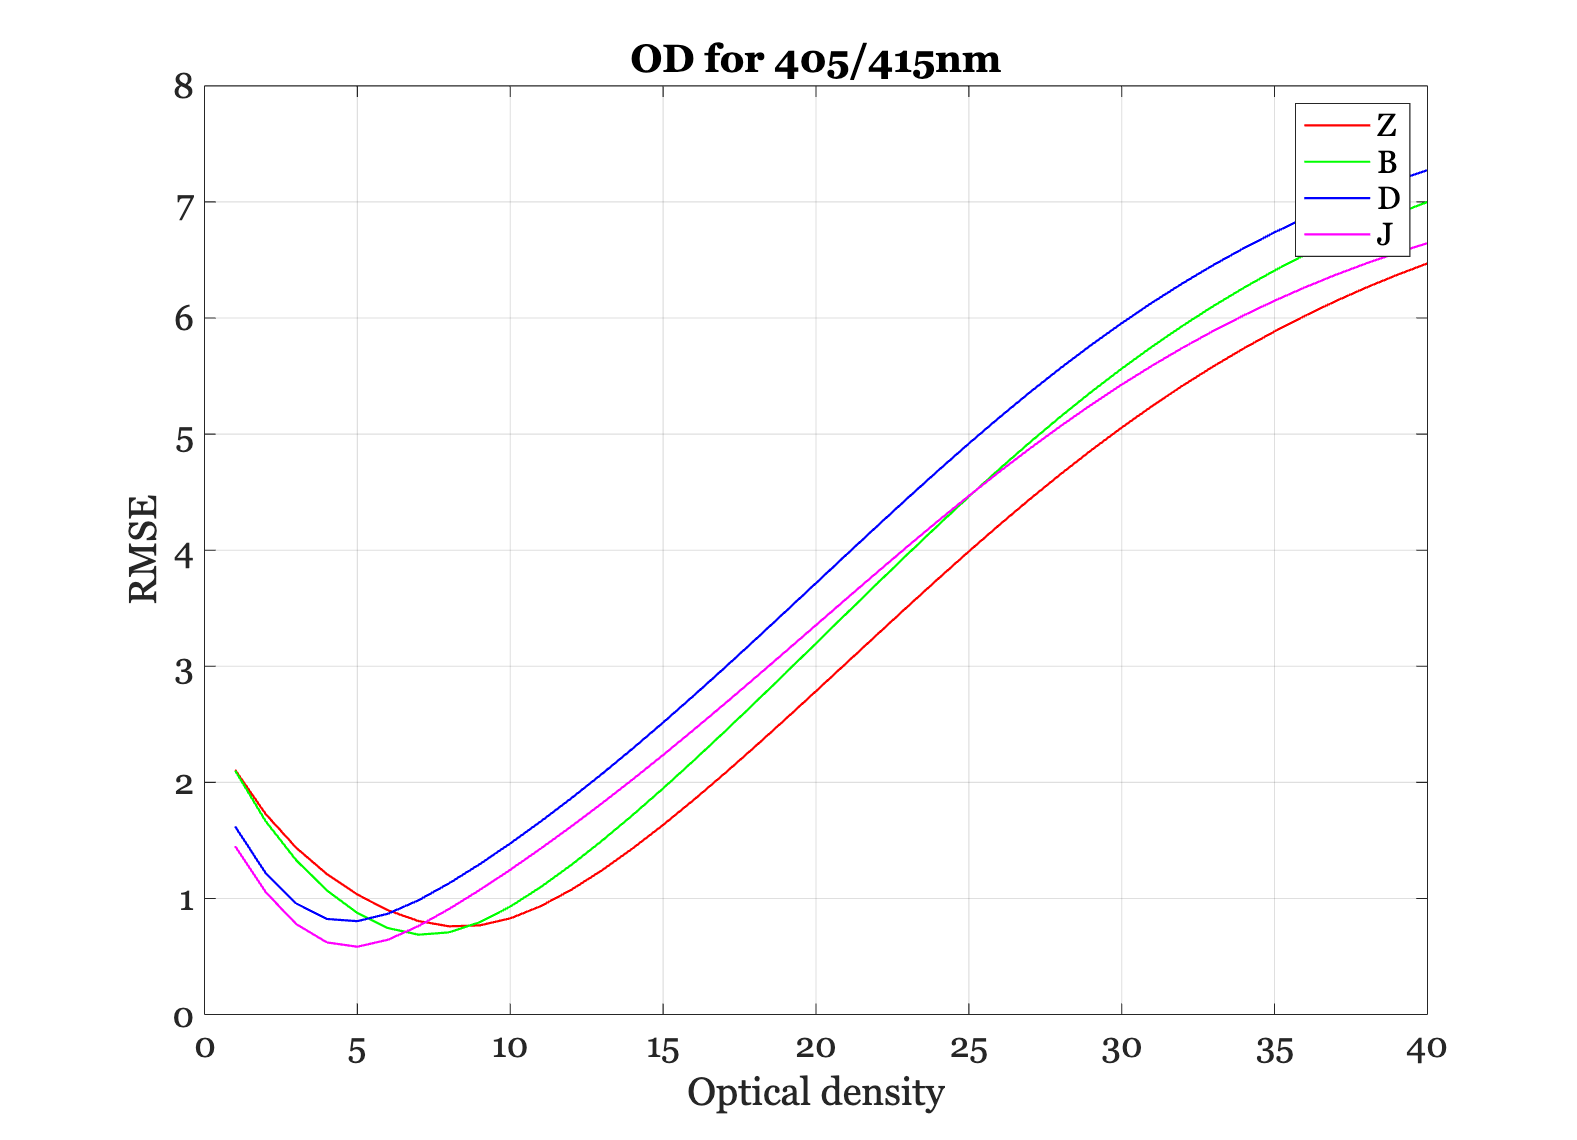


% Plot the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError);
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the estimated optical density and fit the fluorescence data

The fits with oxy applied to the collagen are great.

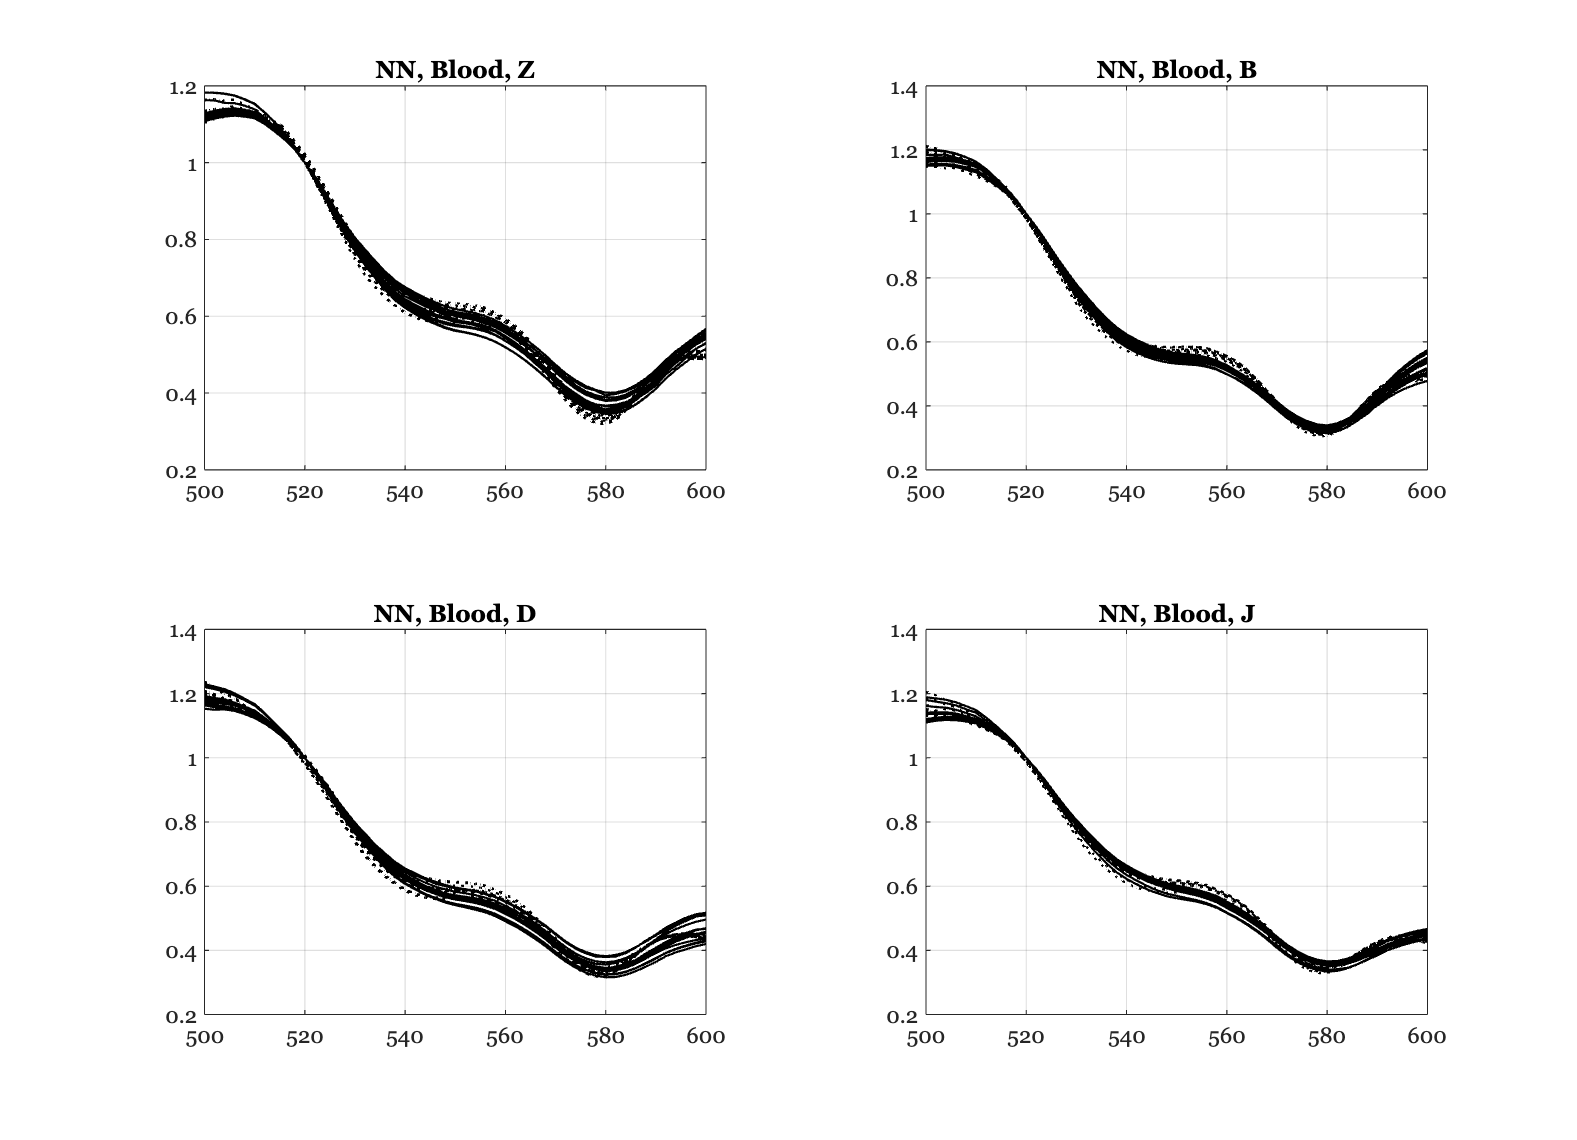

Subject Z
   14.6975   13.8288   14.7508   13.5315   13.8689   13.1281   13.0091   13.6759   13.6849   14.0441   14.0351   13.3447   13.1170   12.8762
    0.5301    0.5697    0.5273    0.5725    0.5548    0.5938    0.6027    0.5642    0.5665    0.5498    0.5495    0.5884    0.6037    0.6132

Subject B
   14.6394   14.4118   14.8951   13.3287   13.7777   14.5068   14.4440   13.5592   13.5829   14.4445   14.3609   14.1476   14.3401
    0.4744    0.4692    0.4510    0.5126    0.4931    0.4755    0.4791    0.5073    0.5068    0.4684    0.4739    0.4901    0.4735

Subject D
   12.9720   13.1226   13.0361   11.6236   11.6404   12.1915   12.2555   12.4317   12.1905   12.3571   11.8896   12.1165   12.2600   12.4348
    0.4058    0.3963    0.4031    0.4940    0.4905    0.4494    0.4478    0.4387    0.4491    0.4496    0.4731    0.4532    0.4436    0.4332

Subject J
   12.4272   12.0434   11.4556   10.8415   10.8775   11.2778   11.2390   10.9482   10.8696   11.2586   11.1863   11.2389   11.2022 

ieFigure;
tiledlayout(2,2);

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);

    lipData = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores,fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);
    
    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

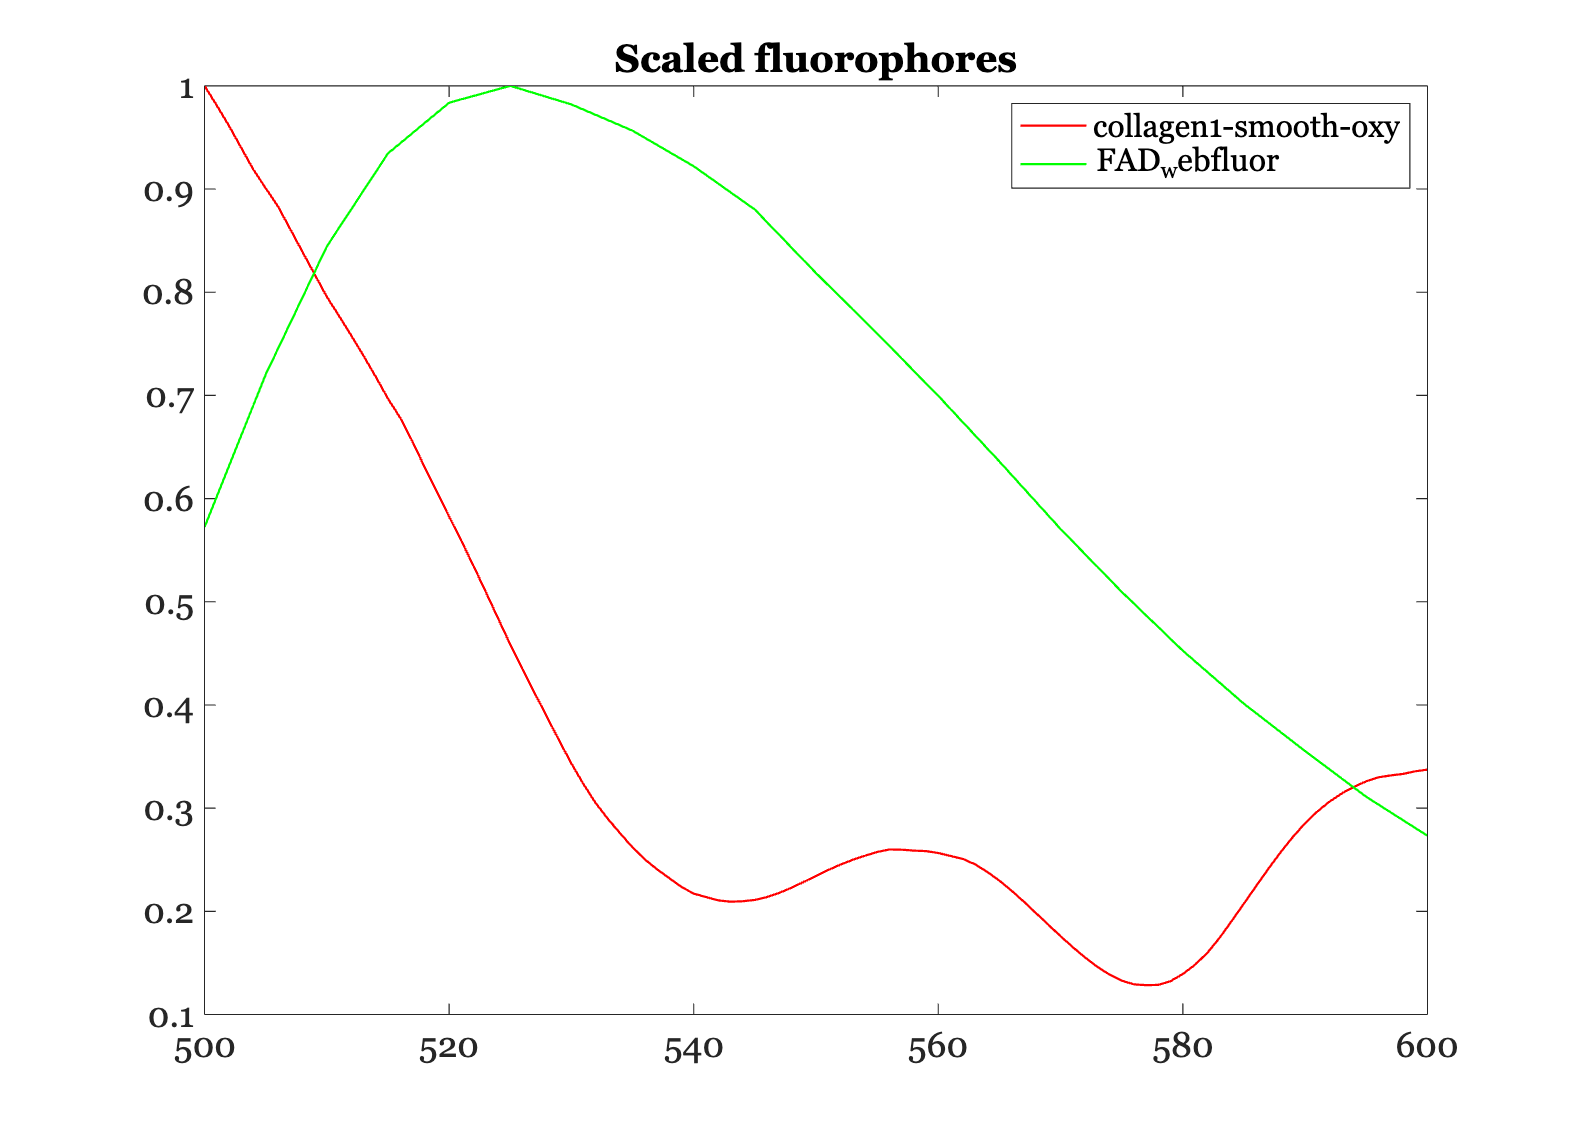


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);

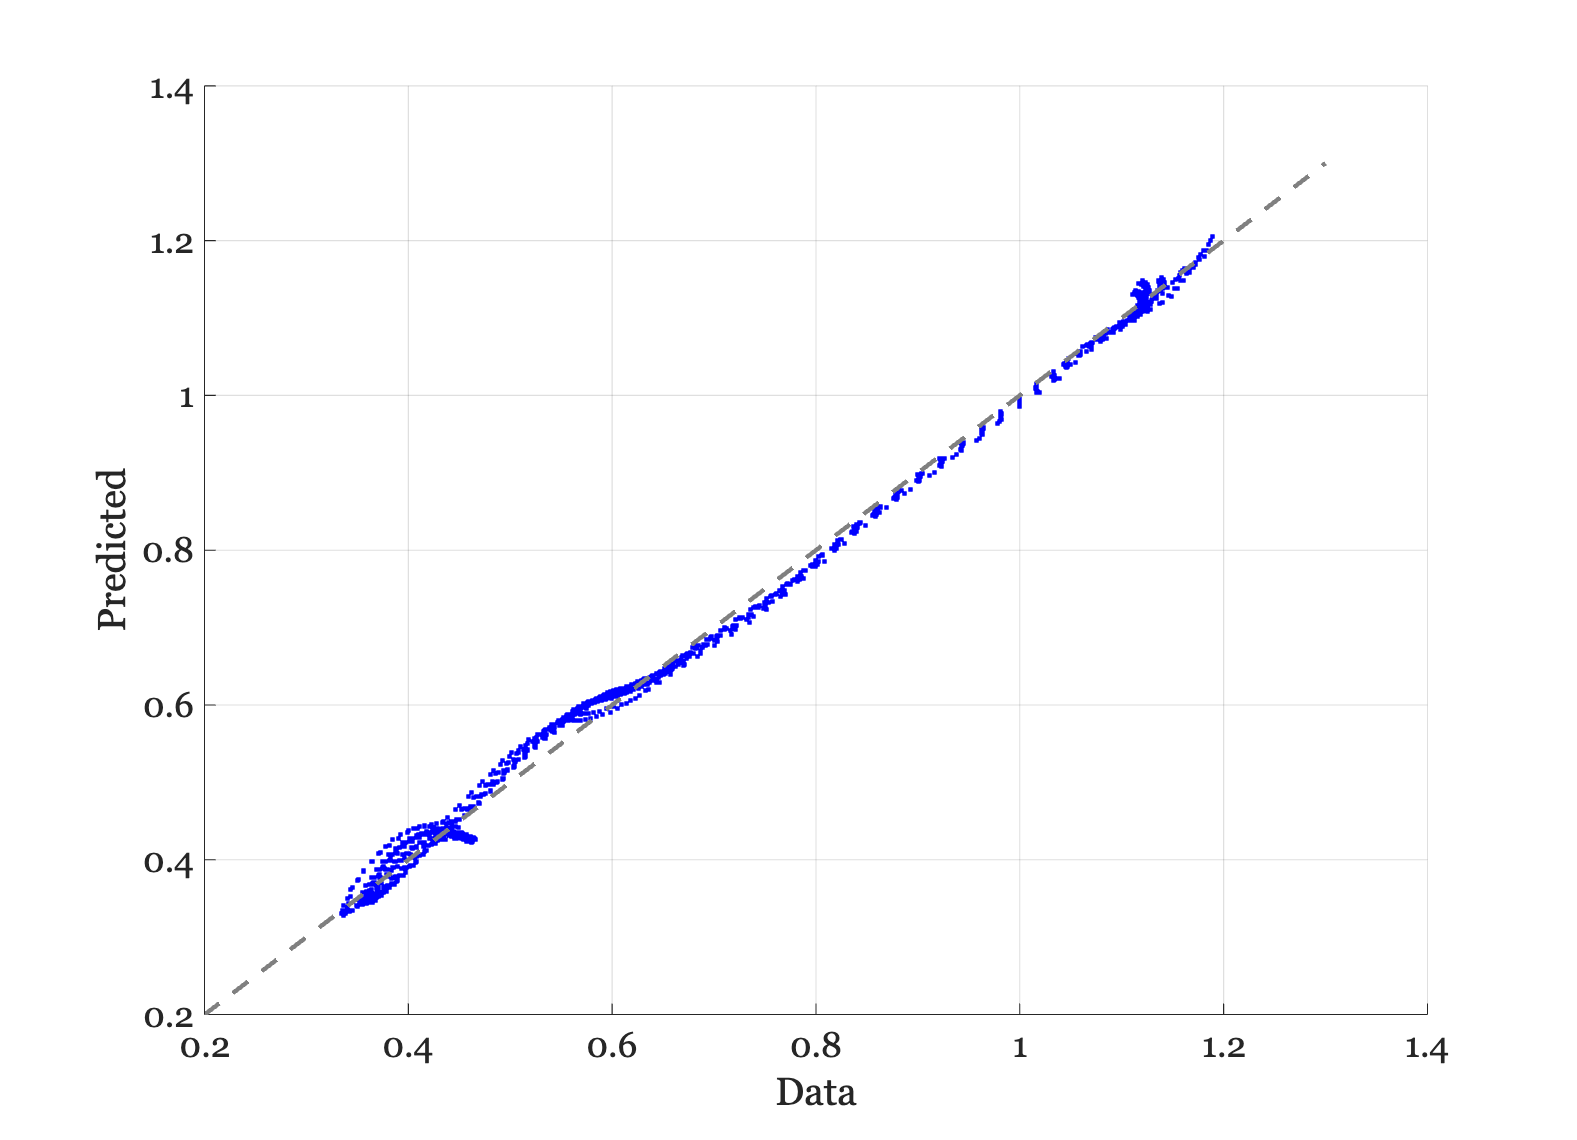


ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## Create 450 nm blood optical density levels

The 450 nm light OD seems to be a bit different, which we explain by saying this wavelength penetrates a bit deeper into the skin.  This makes us wonder whether we need some deoxygenated blood included.

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','lip',...
        'e wave',450);
    lipData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,lipData,wave,odLevels);
end
fprintf('OD across subjects for 450nm %.2f\n',ods);

OD across subjects for 450nm 15.00
OD across subjects for 450nm 16.00
OD across subjects for 450nm 10.00
OD across subjects for 450nm 13.00


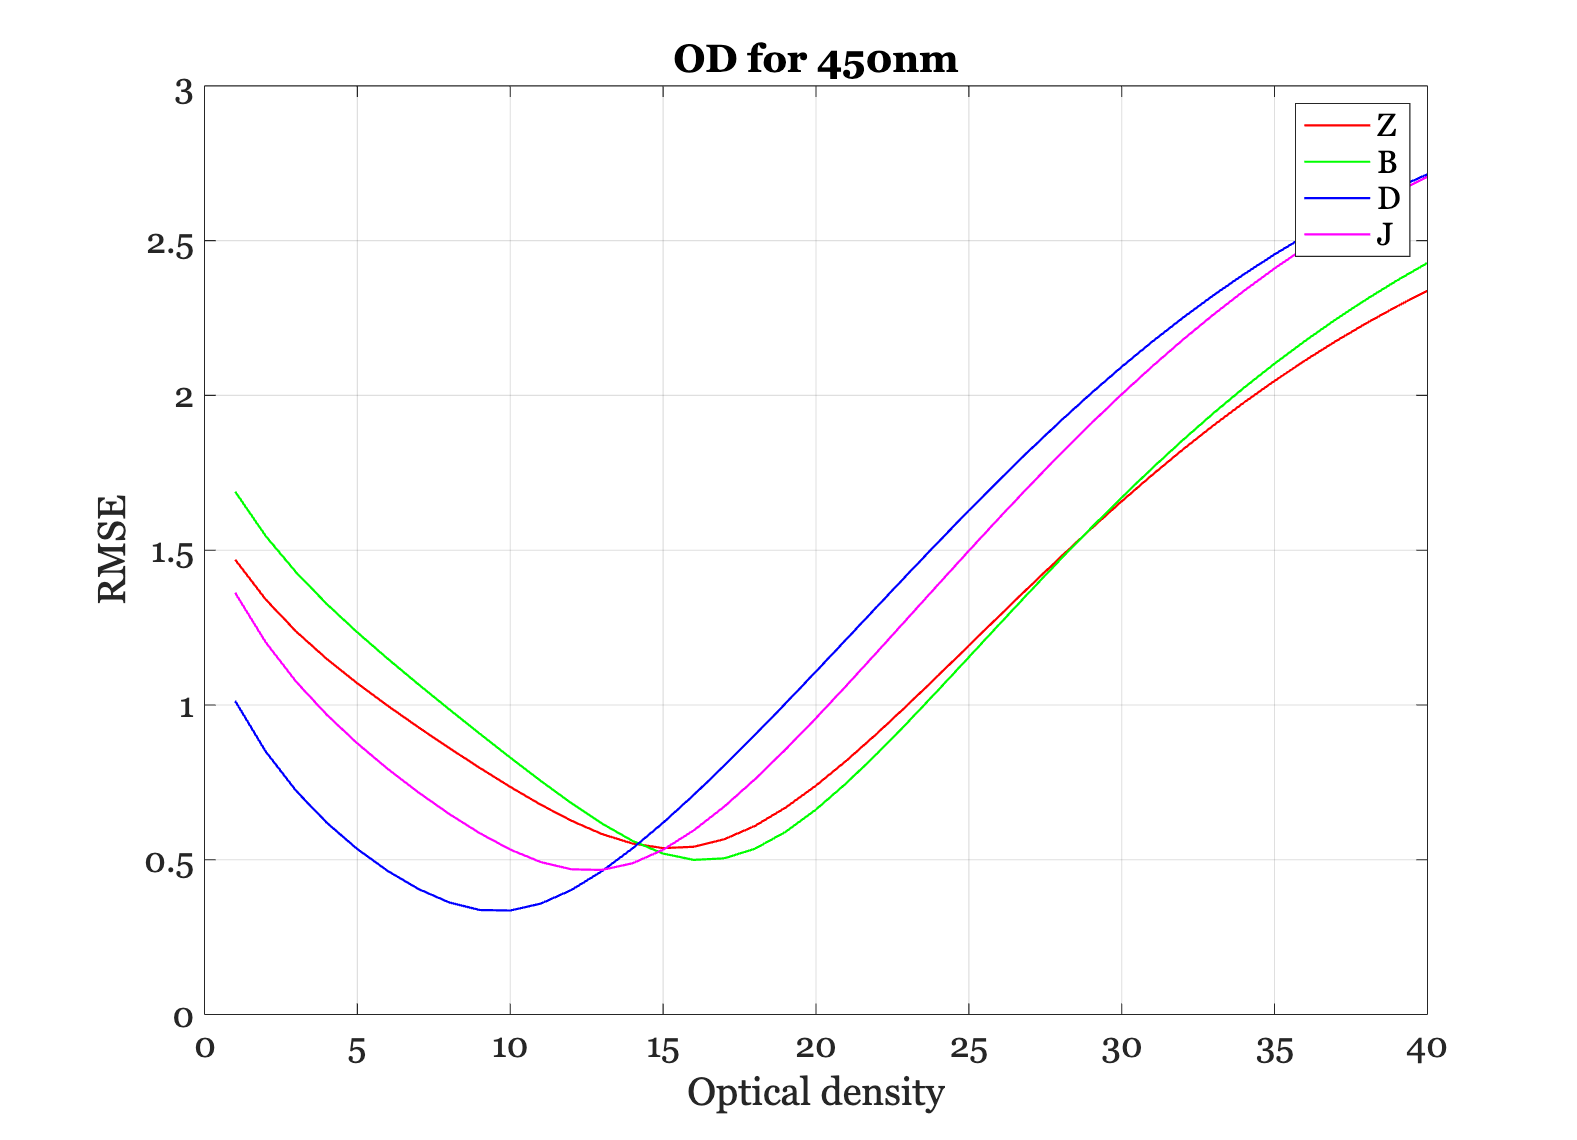

ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');  

## 450 nm excitation light

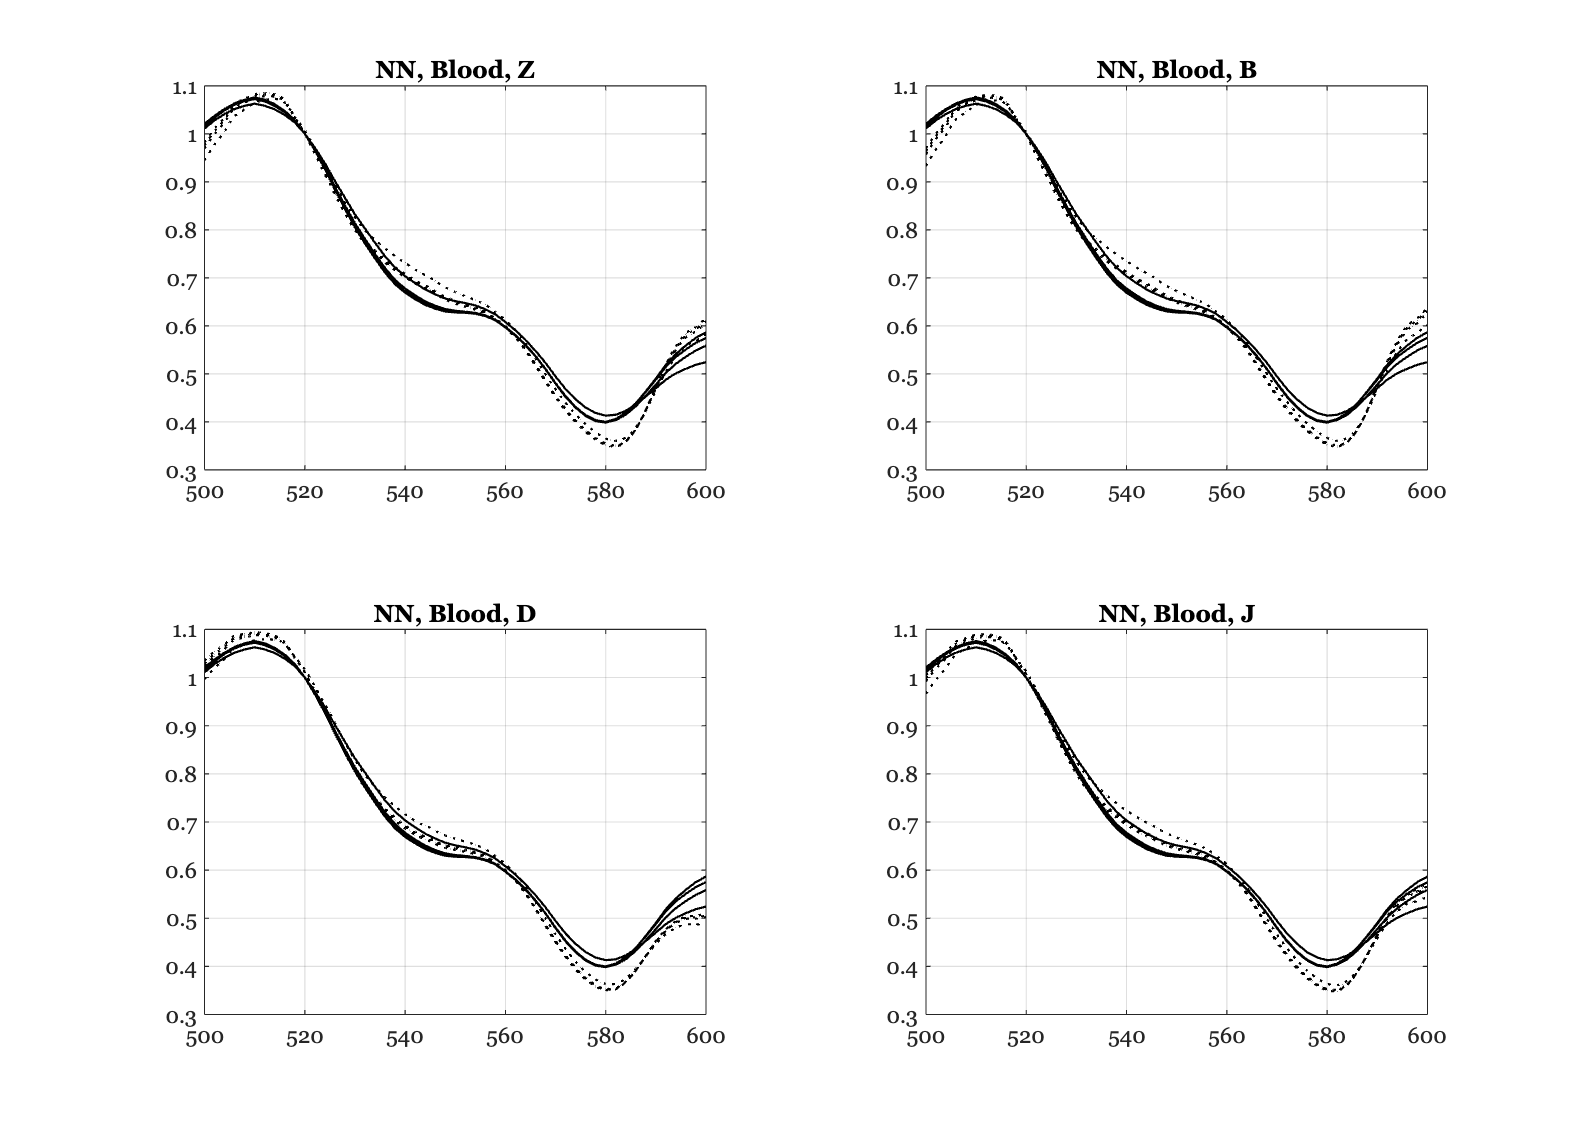

Subject Z
   17.8496   18.1198   16.5374   18.4030
    0.7367    0.7328    0.7638    0.7284

Subject B
   18.9380   19.2383   17.5333   19.5445
    0.7463    0.7424    0.7729    0.7381

Subject D
   13.0827   13.2360   12.1637   13.4250
    0.6776    0.6738    0.7082    0.6688

Subject J
   15.7913   16.0084   14.6509   16.2497
    0.7158    0.7119    0.7442    0.7073



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end


disp(fluorophoreNames'); 

    {'collagen1-smooth-oxy'}
    {'FAD_webfluor'        }



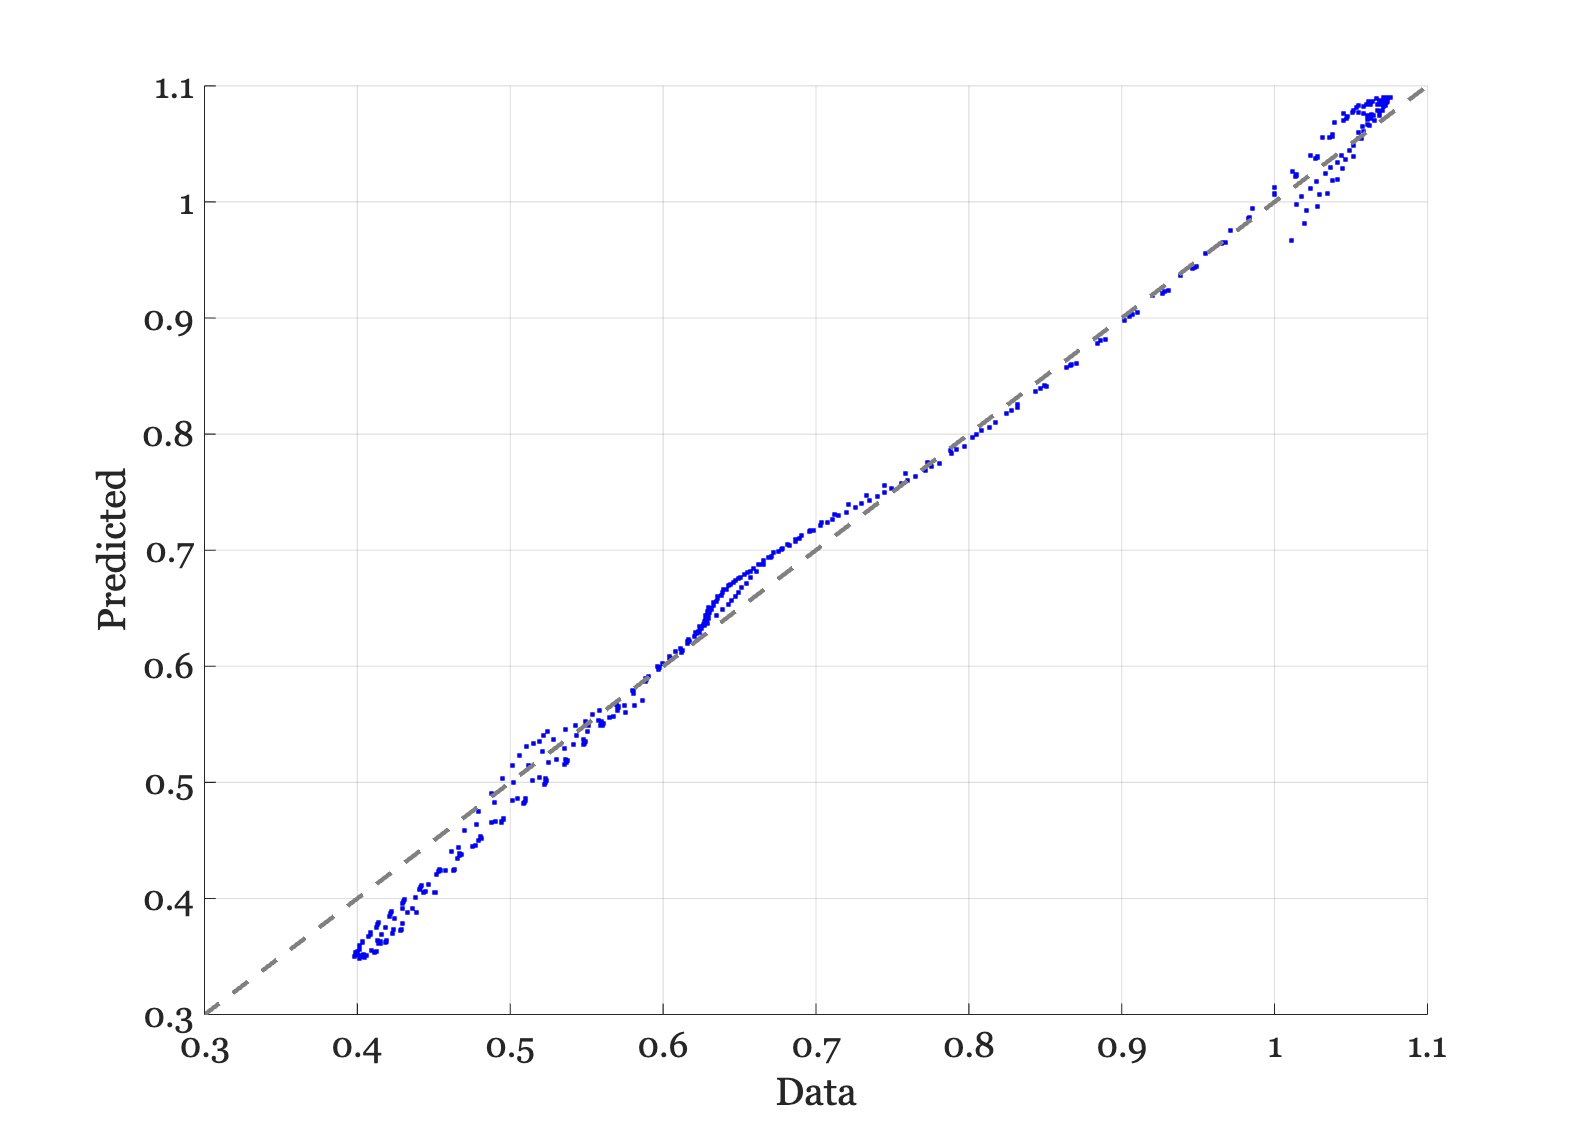


ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## Once more with deoxy

There is no real value add in this case for putting in a lot or a little deoxy.  We tried OD of 5, 30, and 60.  We could see the weights changing but not the RMSE.  Two of the subjects don't use the deoxy at all in any case.

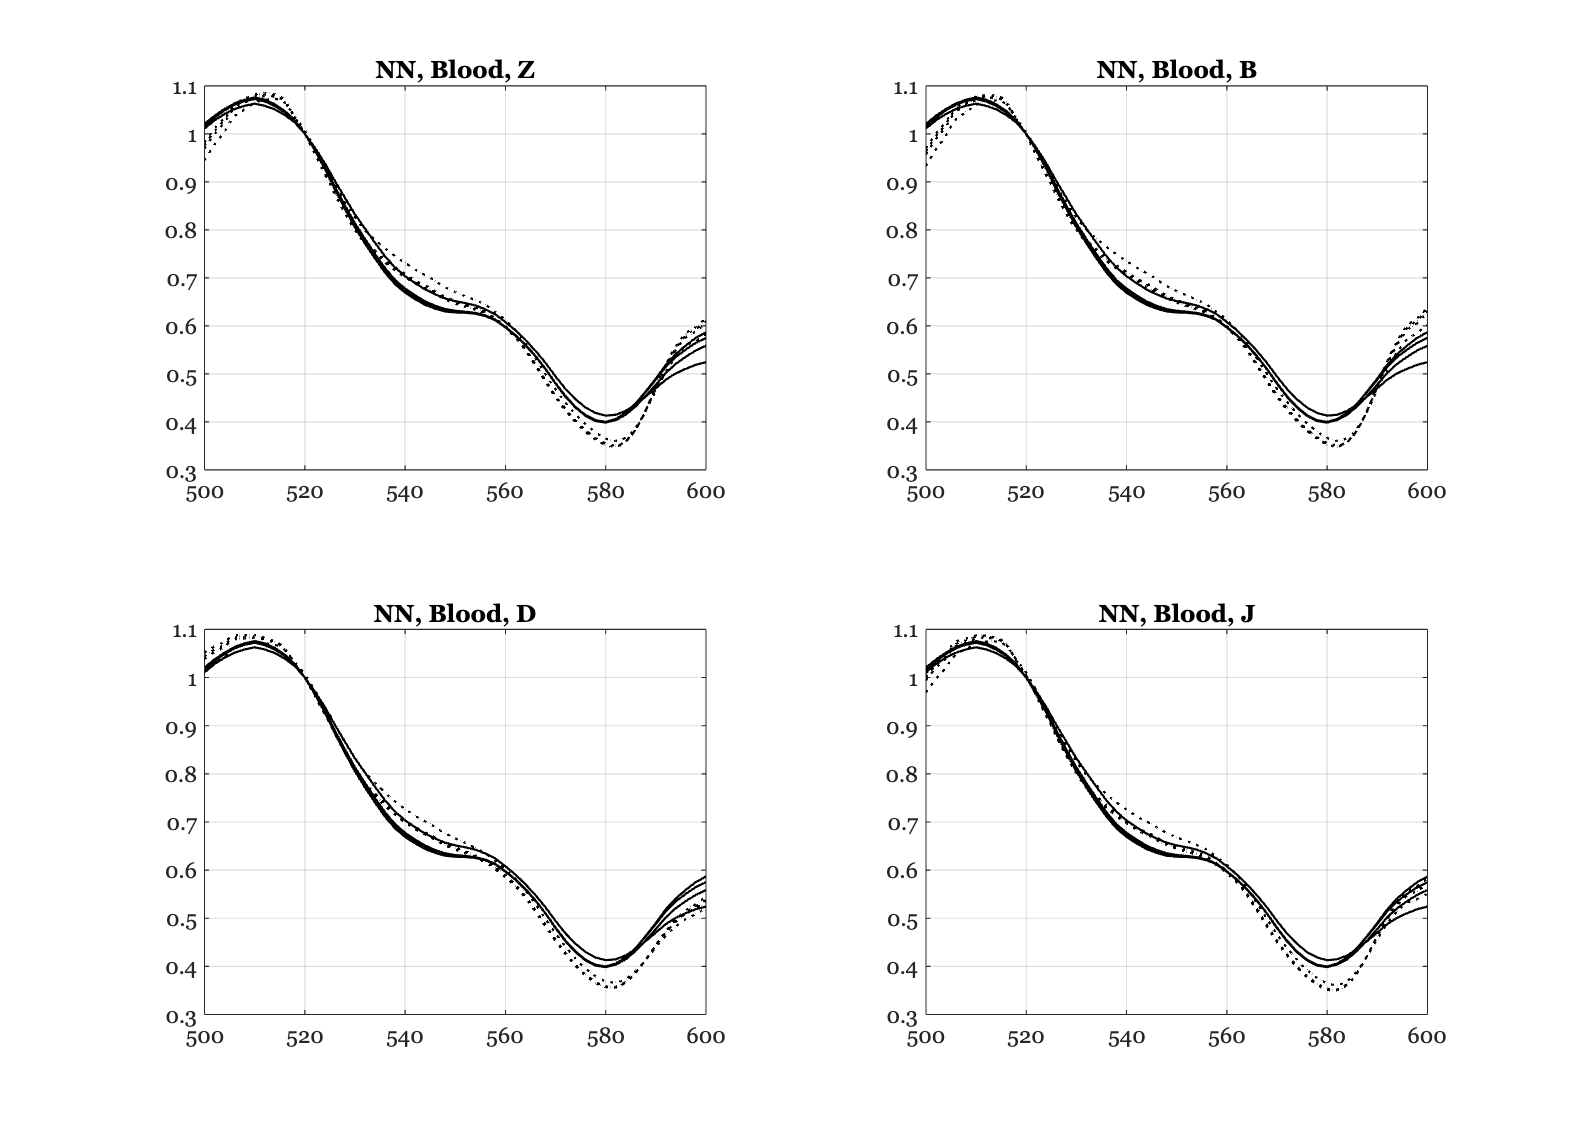

Subject Z
   17.8496   18.1198   16.5374   18.4030
    0.7367    0.7328    0.7638    0.7284
         0         0         0         0

Subject B
   18.9380   19.2383   17.5333   19.5445
    0.7463    0.7424    0.7729    0.7381
         0         0         0         0

Subject D
    8.5237    8.4771    7.6640    8.2597
    0.7043    0.7017    0.7346    0.6991
    9.1113    9.5109    8.9926   10.3229

Subject J
   14.8713   14.8032   13.6094   14.5725
    0.7191    0.7163    0.7480    0.7134
    1.8681    2.4473    2.1148    3.4057



deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 8;
%{
ieFigure;
plot(wave,deoxyblood.transmittance,'b-',wave,oxyblood.transmittance,'r-');
%}

ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames] = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood, ...
        'deoxy',deoxyblood);

    wgtsNN = zeros(size(fluorophores,2),size(lipData,2));

    for dd = 1:size(lipData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    end
    d = lipData - fluorophores*wgtsNN;
    rmse(ii) = norm(d(:),2);

    nexttile
    plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end


disp(fluorophoreNames'); 

    {'collagen1-smooth-oxy'  }
    {'FAD_webfluor'          }
    {'collagen1-smooth-deoxy'}



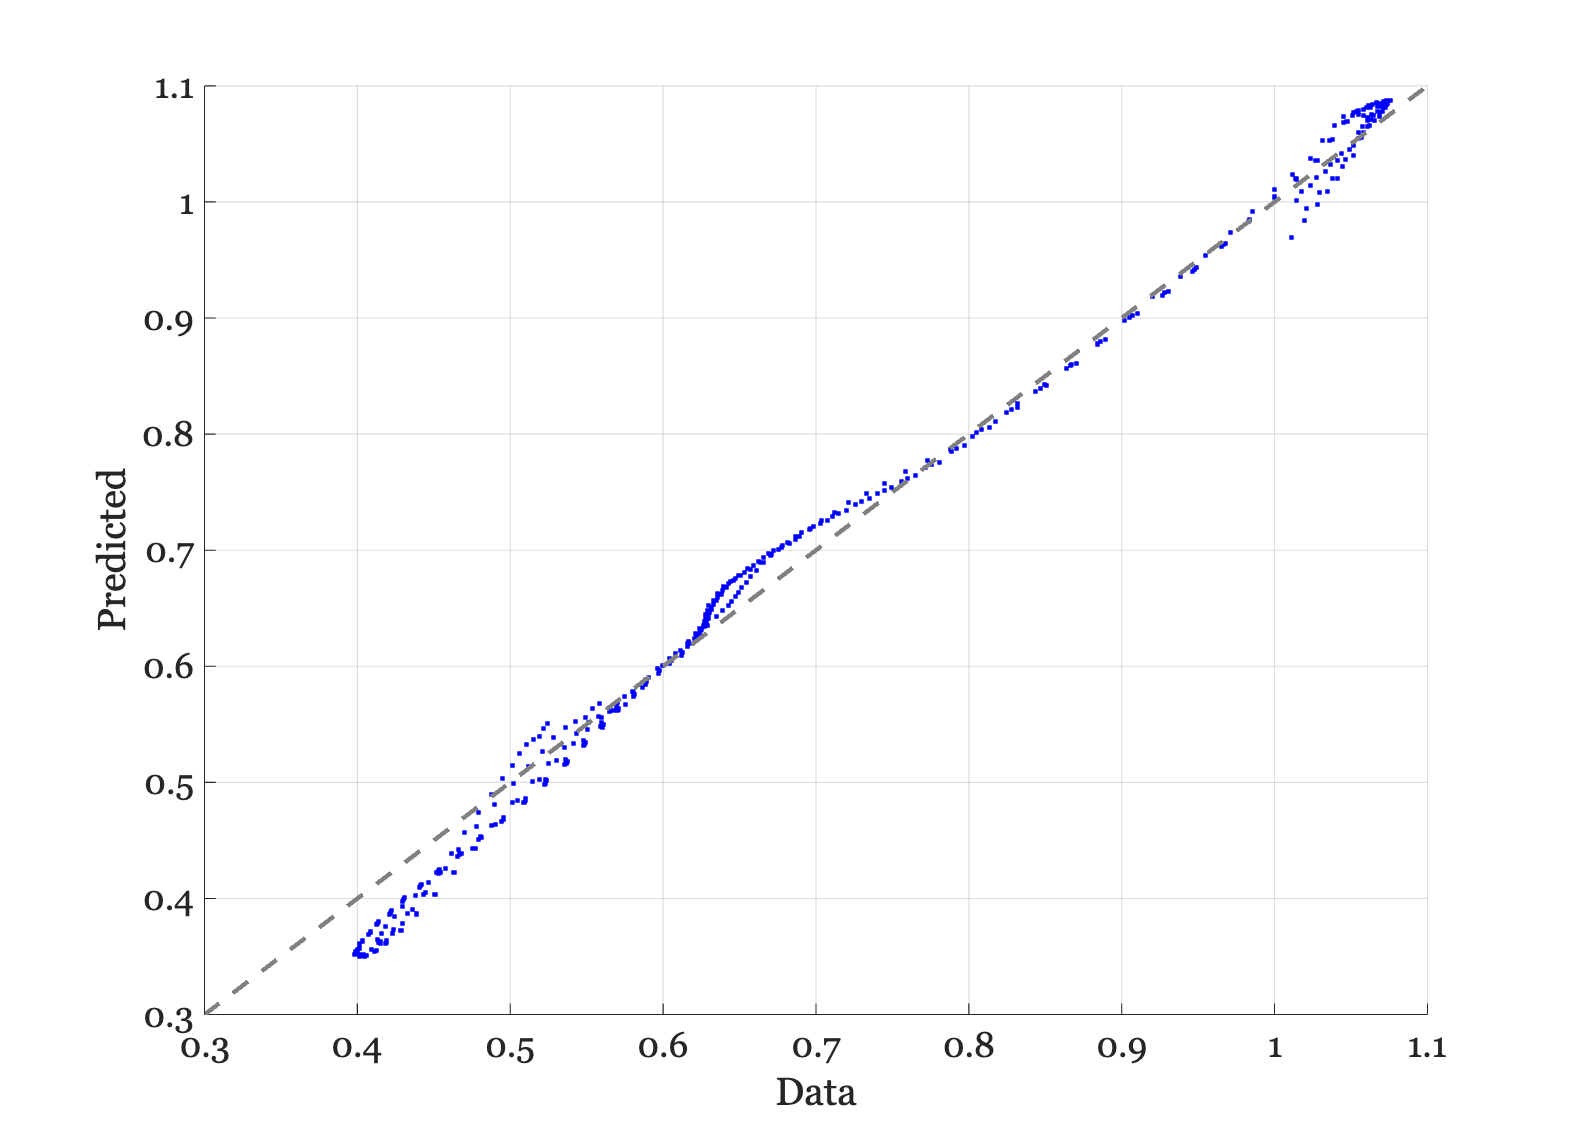

ieFigure;
tmp = fluorophores*wgtsNN;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');